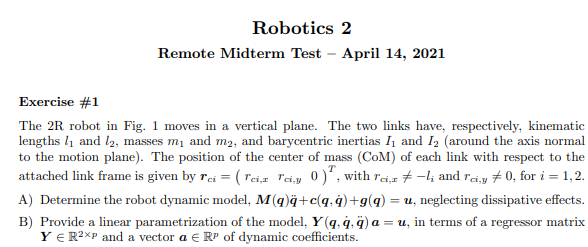

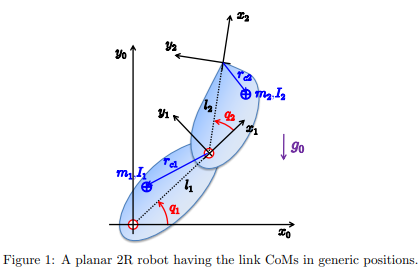

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% % alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% 

% R2Robot=['rr';'xx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% % l(1)=0 %don't do this because dc1 is going to dissaperar
% % z.opt_expr={[l(1)],[0]};%use this instead
% % z.opt_expr={[m(1)],[0]};%use this instead
% % z.opt_expr={dc(1),[r_c_1]};%use this instead
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% 
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% % z.rcdefined=true;
% % z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% r_c_1_x=sym('r_c_x_',[n,1],'real');
% r_c_1_y=sym('r_c_y_',[n,1],'real');
% r_c_1_z=sym('r_c_z_',[n,1],'real');
% 
% z.dc=[r_c_1_x,r_c_1_y,r_c_1_z]';
% %defiing dc method
% z.dc_method=1
% z.dc

% % % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % % %             0       , z.l(2)  , 0   , q(2);]

% % % % 
% % % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

% Ti(1)
% Pc
% M
% % 

% % R_=[cos(z.q(1)+z.q(2)),-sin(z.q(1)+z.q(2));sin(z.q(1)+z.q(2)),cos(z.q(1)+z.q(2))]
% % pc_part_=((R_*[z.l(2)+r_c_2_x;r_c_2_y]))

## Potential energy definition

% % %special potential energy
% % k=sym('k','real')
% % f_u=[(k*z.q(1).^2)/2,0]'

% isMotor=false
% % 
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)
% % [grad_f,PE, U,grad_f_short,PE_short] = getGradient(f_u,z.q)%,gradient computation

% U{:}
% g_q

% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)
% % 

% % C{1}
% % cac
% % S

% [All, dynamicParamsReturn, aM]= getDynamicParameters2([M,diag(g_q),S],q,[z.q_dot],1);
% % [All, dynamicParamsReturn, aM]= getDynamicParameters2([M],q,[z.q_dot],1)

% 
% Msubs = All(:,1:n)
% gsubs = diag(All(:,n+1:2*n))
% Ssubs = All(:,2*n+1:3*n)
% aM
% dynamicParamsReturn

% 
% torqueSubs = Msubs*z.q_ddot + Ssubs*z.q_dot + gsubs% +FSubs*qd

% a_order=aM([3,5,8,1,2,6,4,7])
% [Y, Yshort]=getLinearParametrization(torqueSubs,a_order)

## Exercise 2

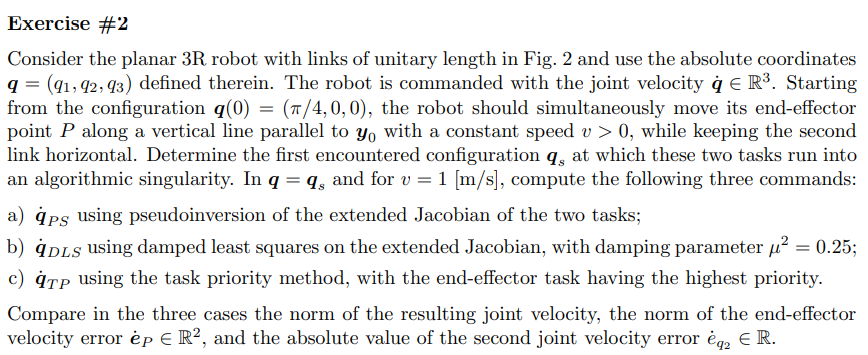

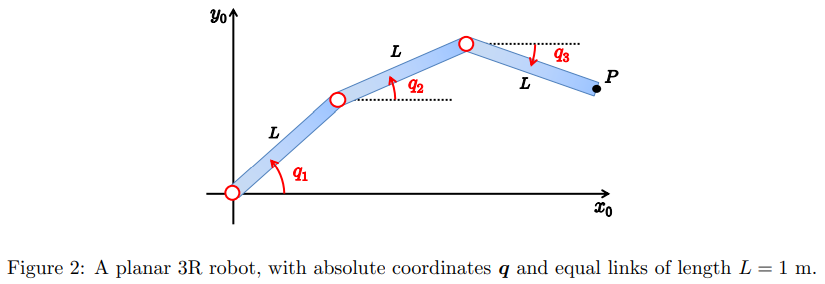

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';

defining z struct

% R2Robot=['rrr';'xxx';sigma]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% % l_0=sym("l","real");
% l_0=1%sym('l','real')
% % h=sym('h','real');
% % h_=1;
% z.opt_expr={[l],[l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% 
% 
% %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

Defining task order

% pd={sym('pd_1_',[2,1],'real'),sym('pd_2_',[1,1],'real')};
% pd_dot={sym('pd_dot_1_',[2,1],'real'),sym('pd_dot_2_',[1,1],'real')};
% 
% % px_0=sym('P_x_0','real');
% % z.task_defined={struct('f',[px_0;l_0*(sin(z.q(1))+sin(z.q(2))+sin(z.q(3)))],'pd_',pd{2}),struct('f',q(2),'pd_',pd{1})} ;%pc is note necessary
% 
% % z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
% 
% z.task_defined={struct('f','end_effector','pd_',pd{1},'pd_dot_',pd_dot{1}),struct('f',q(2),'pd_',pd{2},'pd_dot_',pd_dot{1})} ;%pc is note necessary
% 
% %
% z.task_defined

% % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% f
% J
% % M
% % Pc
% % simplify((Ti'))
% % vc
% % simplify(Trans.PTotal)
% % Trans.PPartial{:}
% J

% q_=[pi/4,0,0]';
% to_replace=[l_0;z.q]
% to_replace_=[1;q_]
% P_0_=subs(f(1:2),to_replace,to_replace_)
% 
% qs1=vpa(acos((P_0_(1)-1)/2));
% 
% qs_=[qs1,0,qs1]'
% 
% to_replace=[l_0;z.q]
% to_replace_=[1;qs_]
% P_0_s_=subs(f(3),to_replace,to_replace_)
% 

## rank of J

% rank(J)
% J(:,1:end)
% simplify(det(J(:,1:end)))

% rd_1=f(1:2,:)
% rd_2=f(3:end,:)
% 
% 
% 

## redundancy task with prioriy

% replace_values=false
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[pi/4,0,0]';
% q_s1=[0.5480; 0; 0.548];
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% % q_dot_k{:};
% % z_task.J_k{:};
% % z_task.J_k_pinv{:};
% % z_task.P_A_k{:};
% % 
% % % z_task.q_dot_k_{:}
% % % z_task.J_k_{:}
% % % z_task.J_k_pinv_{:}
% % % z_task.P_A_k_{:}

## defining function trajectory

% z_path_params.func_name="vertical_line"; %moves in the y axis
% z_path_params.replacevars=true;
% z_path_params.dir=1;%1 up, 0 going down
% z_path_params.v_=[0,1]';
% % z_path_params.P_=[sym('P_x_0','real'),sym('P_y_0','real')];
% 
% xyonly_=true
% z_path = common_trajectory_func(z_path_params,xyonly_);

% z_path.rd
% z_path.rd_t
% z_path.rd_t_dot
% z_path.rd_t_ddot
% if(z_path_params.replacevars)
%     z_path.rd_
%     z_path.rd_dot_
%     z_path.rd_ddot_
%     
%     z_path.rd_t_
%     z_path.rd_t_dot_
%     z_path.rd_t_ddot_
%     
% end

% P_0=subs(z_path.rd_,[z_path.P_0;z_path.P(2)],[P_0_;0])%[10,0]';
% rd_dot_0_=subs(z_path.rd_dot_,z_path.v,[1,1]')%sym([0,1,0])'; %v=1
% z_task.f_k{1}
% f_k_red=simplify(subs(z_task.f_k{1},q,[q(3),0,q(3)]'))
% %weknow thath q1=q3
% 
% q_sol1=solve(f_k_red(1)==P_0(1),q(3))
% 
% %choosing the positive answer
% q_sol2_=vpa([q_sol1(2),0,q_sol1(2)])'
% % [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution
% f_k_red_=subs(f_k_red,q,q_sol2_) %% optimal solution
% % q_red=[q(1),q(2),q(3)]'
% % % q_dot_red=[q_dot(1),q_dot(3)]'
% % J_k_red=jacobian(f_k_red,q_red)

% % 
% q_dot_=z.q_dot;
% q_dot_(2)=0

% simplify(det(J))
% 

J_A_0 evaluation

% J_A_0_=subs(J,q,q_)
% q_dot_0_=pinv(J_A_0_)*[rd_dot_0_;0]%%succesfully done

**J_A_s evaluation**

**Pseudoinversion**

% % P_0=subs(z_path.rd,z_path.theta,pi/2)%[10,0]';
% vpa(P_0)
% rd_dot_s_=z_path.rd_dot_; %v=1
% q_s_=q_sol2_
% J_A_s_=subs(J,q,q_s_)
% pinv(J_A_s_)
% q_dot_s_=pinv(J_A_s_)*[rd_dot_s_;0]%%succesfully done

**J_A_s evaluation**

**Damped Least Squares**

% % P_0=subs(z_path.rd,z_path.theta,pi/2)%[10,0]';
% vpa(P_0)
% rd_dot_s_=z_path.rd_dot_; %v=1
% q_s_=q_sol2_
% J_A_s_=round(subs(J,q,q_s_),4)
% 
% pinv(J_A_s_)
% miu=sqrt(0.25)
% J_A_s_damp_=Inverse_Damped_Jacobian(J_A_s_,miu)
% q_dot_damp_s_=J_A_s_damp_*[rd_dot_s_;0]%%succesfully done

## Task Priority

## redundancy task with prioriy

% replace_values=true
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0.5480; 0; 0.548]
% % q_s1=[0.5480; 0; 0.548];
% PC_EE.pd_dot_{1}=[0,1]';
% PC_EE.pd_dot_{2}=0;
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% z_task.q_dot_k_{2}

## tessting solutions

% rd_dot_s2_=J_A_s_*q_dot_s_%% succesfully completed!!!
% 
% rd_dot_s2_=J_A_s_*q_dot_damp_s_%% succesfully completed!!!
% 
% rd_dot_s2_=J_A_s_*z_task.q_dot_k_{2}%% succesfully completed!!!


## Exercise 3

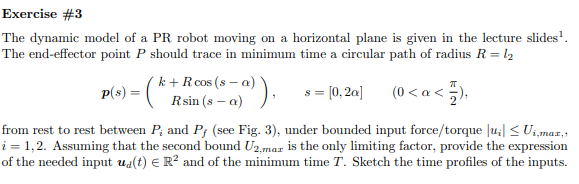


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,1];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,0,-g0]';

R2Robot=['pr';'xx';sigmaD]

R2Robot = 3×2 char array
    'pr'
    'xx'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
% z.opt_expr={[l(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
% z.prismatic_CoM_method(2)=2; %apy attention to this
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% % %             0       , z.l(2)  , 0   , q(2);]

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
       

si falla aquí está el error


anglerot = 1×1 cell array
    {4×4 sym}


$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} 1 & -l_{2}\,\sin\left(q_{2}\left(t\right)\right)\\ 0 & l_{2}\,\cos\left(q_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cc} q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} {\dot{q}}_{1} & {\dot{q}}_{1}-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & {\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{2}\,\left({{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}-2\,\sin\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{1}}^{2}\right)}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: [1×1 sym]
    Ti: [1×2 sym]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: [1×1 sym]
                     Ti: [1×2 sym]
                      M: [2×2 sym]


% Ti(1)
% T
% Pc
M

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right)\\ -{\mathrm{dc}}_{2}\,m_{2}\,\sin\left(q_{2}\right) & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

Pc

$$Pc = \left(\begin{array}{cc} q_{1} & q_{1}+{\mathrm{dc}}_{2}\,\cos\left(q_{2}\right)\\ 0 & {\mathrm{dc}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot);

>> Getting  the Christoffel’sym. Might take a while...


S

$$S = \left(\begin{array}{cc} 0 & -{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$

## MODEL

M*z.q_ddot+S*z.q_dot

$$ans = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,m_{2}\,\cos\left(q_{2}\right)\,{{\dot{q}}_{2}}^{2}+{\ddot{q}}_{1}\,\left(m_{1}+m_{2}\right)-{\mathrm{dc}}_{2}\,m_{2}\,{\ddot{q}}_{2}\,\sin\left(q_{2}\right)\\ {\ddot{q}}_{2}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\right)-{\mathrm{dc}}_{2}\,m_{2}\,{\ddot{q}}_{1}\,\sin\left(q_{2}\right) \end{array}\right)$$

## Bang Cost Bang

m_=2

m_ = 2

l_=0.5

l_ = 0.5000

% theta_T=pi;
% theta_s_=theta_T/6
I_=m_*l_^2/12+m_*(l_/2)^2

I_ = 0.1667

% g_0=9.81

g_0 = 9.8100

d_=l_/2

d_ = 0.2500

% tau_g_max_=m_*g_0*d_

tau_g_max_ = 4.9050

% tau_max_=200

tau_max_ = 200

% sin(theta_s_)

ans = 0.5000

% T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))

T_min = 0.1189

## bang cost bang profile

T=sym('T','real');
V1=sym('V1','real');
A1=sym('A_max','real');
alpha=sym('alpha','real');
% T_=1*T_min%1.2165;

T_ = 0.1189

% T_=1.2165;
% Ts_=T_/4
alpha_=pi/6

alpha_ = 0.5236

U2_max=4

U2_max = 4

U1_max=14%2*alpha_*m_*d_/I_*U2_max

U1_max = 14

A2_=U2_max/I_

A2_ = 24

% Ts=T/4;
% V1=Ts*A1;
% V1_=Ts_*A1_;

qA=[-alpha_]'

qA = -0.5236

qB_=[alpha_]'

qB_ = 0.5236

qB=sym('qB',[2,1],'real');

I_0=1

I_0 = 1

% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
[qa_piece2,Tres_,V_,qa_piece_sym] = BangBangPRofile(qA(1,1),qB_(1,1), A2_)

$$qa\_piece = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2}-\frac{\pi }{6} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{\pi }{6}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 24.0 & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ -24.0 & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 24.0\,t & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ 10.026513098524002298717050507548-24.0\,t & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 12.0\,t^{2}-0.52359877559829887307710723054658 & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ 5.0132565492620011493585252537741\,t-12.0\,{\left(t-0.20888568955258338122327188557392\right)}^{2}-1.0471975511965977763438354046548 & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right. \end{array}\right)$$

Tres_ = 0.4178

V_ = 5.0133

$$qa\_piece\_sym = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(\frac{T}{2}-t\right)+\frac{A_{1}\,T}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2}-\frac{\pi }{6} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ \frac{A_{1}\,T^{2}}{8}-\frac{\pi }{6}-\frac{A_{1}\,{\left(\frac{T}{2}-t\right)}^{2}}{2}-\frac{A_{1}\,T\,\left(\frac{T}{2}-t\right)}{2} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)$$

T_=Tres_

T_ = 0.4178

simplify(qa_piece_sym)

$$ans = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -A_{1} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ A_{1}\,\left(T-t\right) & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right.\\ \left\{ \begin{array}{cl} \sigma_{1}-\frac{\pi }{6} & \text{ if }t<\frac{T}{2}\wedge 0\leq t\\ -\frac{A_{1}\,T^{2}}{4}+A_{1}\,T\,t-\sigma_{1}-\frac{\pi }{6} & \text{ if }t<T\wedge T\leq 2\,t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{1}\,t^{2}}{2} \end{array}$$

round(simplify(qa_piece2),6)

$$ans = \left(\begin{array}{c} \left\{ \begin{array}{cl} 24.0 & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ -24.0 & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.000001\,\mathrm{round}\left(24000000.0\,t\right) & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ 0.000001\,\mathrm{round}\left(10026513.098524002298717050507548-24000000.0\,t\right) & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.\\ \left\{ \begin{array}{cl} 0.000001\,\mathrm{round}\left(12000000.0\,t^{2}-523598.77559829887307710723054658\right) & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ 0.000001\,\mathrm{round}\left(-12000000.0\,t^{2}+10026513.098524002298717050507548\,t-1570796.3267948966796105635787631\right) & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right. \end{array}\right)$$

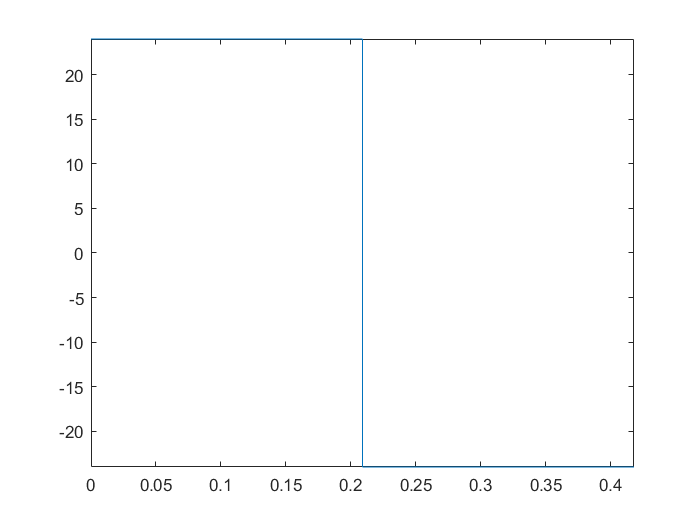


fplot(qa_piece2(1,:),[0,T_])

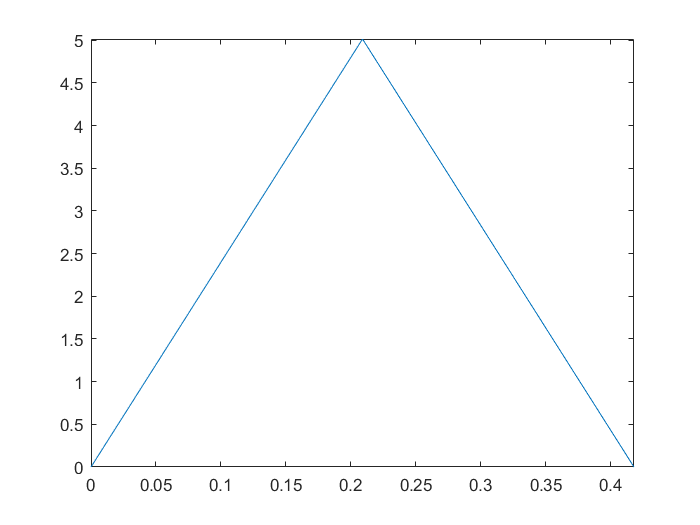

figure
fplot(qa_piece2(2,:),[0,T_])

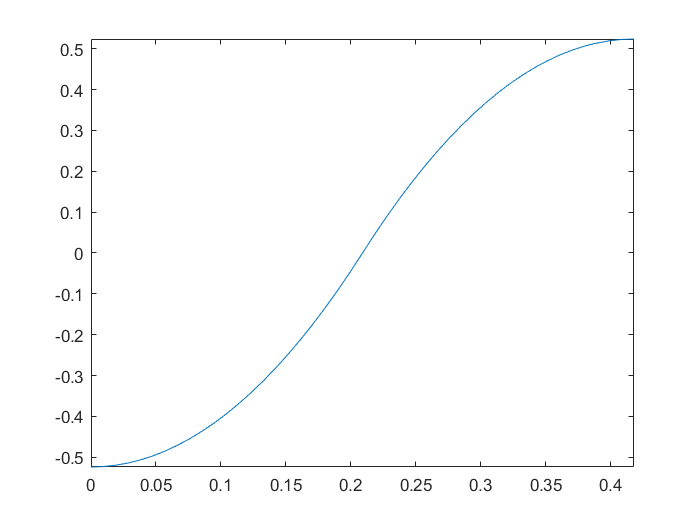

figure
fplot(qa_piece2(3,:),[0,T_])

figure
% [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% tau_2=int(qa_piece2,t)

## torques

u1=-d_*m_*cos(qa_piece2(3,:))*(qa_piece2(2,:))^2-d_*m_*sin(qa_piece2(3,:))*(qa_piece2(1,:))

$$u1 = \begin{array}{l} \left\{ \begin{array}{cl} -12.0\,\sin\left(12.0\,t^{2}-0.52359877559829887307710723054658\right)-288.0\,t^{2}\,\cos\left(12.0\,t^{2}-0.52359877559829887307710723054658\right) & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ -12.0\,\sin\left(\sigma_{1}\right)-\frac{\cos\left(\sigma_{1}\right)\,{\left(24.0\,t-10.026513098524002298717050507548\right)}^{2}}{2} & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=12.0\,{\left(t-0.20888568955258338122327188557392\right)}^{2}-5.0132565492620011493585252537741\,t+1.0471975511965977763438354046548 \end{array}$$

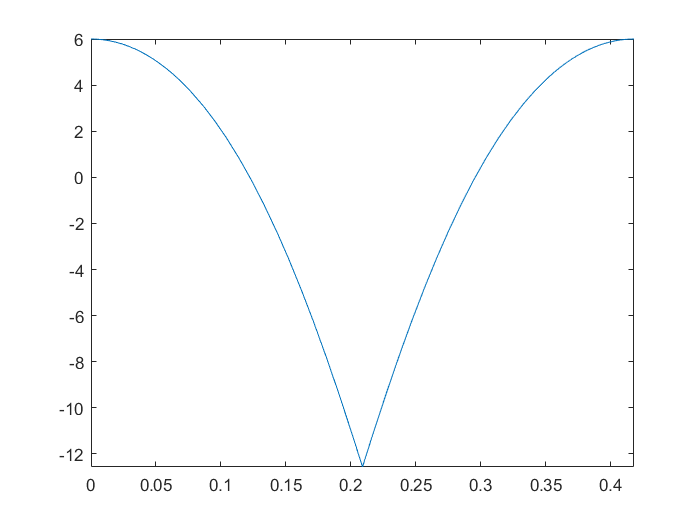

fplot(u1,[0,T_])

figure

u2=(qa_piece2(1,:))*I_

$$u2 = \left\{ \begin{array}{cl} 4.0 & \text{ if }t\in \left[0.0,0.20888568955258338122327188557392\right)\\ -4.0 & \text{ if }t\in \left[0.20888568955258338122327188557392,0.41777137910516676244654377114784\right) \end{array}\right.$$

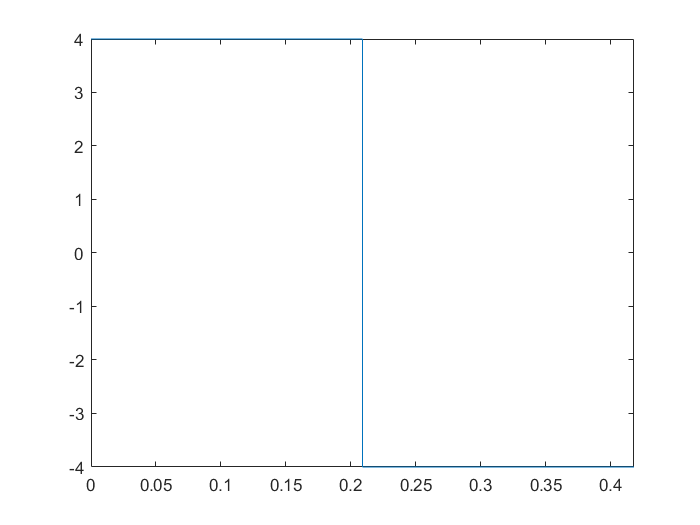

fplot(u2,[0,T_])

figure